# **Desarrollo del Algoritmo**

clear all
close all

%%% Leemos el archivo:
raw = readcell('Data_SIN_ANOTACIONES.csv', 'FileType', 'spreadsheet');
textData = raw(:,1);
splitData = cellfun(@(x) strsplit(x, ','), textData, 'UniformOutput', false);
dataMatrix = vertcat(splitData{:});

headers = dataMatrix(1,:);
informacion = dataMatrix(2:end,:);

data = cell2table(informacion,'VariableNames',headers)

data = 726×19 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_BoundingBox    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter      Leu_median_Solidity     Leu_median_Perimeter     Leu_median_Intensity     Par_median_Area    Par_median_BoundingBox    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter      Par_median_Solidity     Par_median_Perimeter    Par_median_Intensity 
    _______________________    _________________________    ___________________    _______________    ______

## **1. Exploratory Data Analysis (EDA)**

#### 1.1. Visión General

[alto, ancho] = size(data) 

alto = 726

ancho = 19

variables = data.Properties.VariableNames

variables = 1×19 cell array
    {'ImageName'}    {'GlobulosBlancosDetectados'}    {'ParasitosDetectados'}    {'Leu_median_Area'}    {'Leu_median_BoundingBox'}    {'Leu_median_Eccentricity'}    {'Leu_median_Circularity'}    {'Leu_median_Diameter'}    {'Leu_median_Solidity'}    {'Leu_median_Perimeter'}    {'Leu_median_Intensity'}    {'Par_median_Area'}    {'Par_median_BoundingBox'}    {'Par_median_Eccentricity'}    {'Par_median_Circularity'}    {'Par_median_Diameter'}    {'Par_median_Solidity'}    {'Par_median_Perimeter'}    {'Par_median_Intensity'}


Las variables de las que disponemos son las siguientes:

- **ImageName**: nombre de la imagen 

- **GlobulosBlancosDetectados**: número de glóbulos blancos detectados en la imágen

- **ParasitosDetectados**: número de parásitos detectados en la imágen

- **Leu_median_Area**: mediana del área de los glóbulos blancos en la imágen (píxeles ^2)

- **Leu_median_BoundingBox**: mediana del BoundingBox de los glóbulos blancos en la imágen. Es decir, mediana entre las coordenadas x e y de los glóbulos blancos de la imágen y su alto y ancho.

- **Leu_median_Eccentricity**: mediana de la excentricidad de los glóbulos blancos en la imágen (sin unidad).

- **Leu_median_Circularity**: mediana de la circularidad de los glóbulos blancos en la imágen (sin unidad).

- **Leu_median_Diameter**: mediana del diámetro de los glóbulos blancos en la imágen (píxeles).

- **Leu_median_Solidity**: mediana  de la solidez los glóbulos blancos en la imágen (sin unidad).

- **Leu_median_Perimeter**: mediana del área de los glóbulos blancos en la imágen (píxeles).

- **Leu_median_Intensity**: mediana de la intensidad de los glóbulos blancos en la imágen (sin unidad).

- **Par_median_Area**: mediana del área de los parásitos en la imágen.

- **Par_median_BoundingBox**: mediana del BoundingBox de los parásitos en la imágen. Es decir, mediana entre las coordenadas x e y de los parásitos de la imágen y su alto y ancho.

- **Par_median_Eccentricity**: mediana de la excentricidad de los parásitos en la imágen.

- **Par_median_Circularity**: mediana de la circularidad de los parásitos en la imágen.

- **Par_median_Diamete**: mediana del diámetro de los parásitos en la imágen.

- **Par_median_Solidity**: mediana de la solidez de los parásitos en la imágen.

- **Par_median_Perimeter**: mediana del perímetro de los parásitos en la imágen.

- **Par_median_Intensity**: mediana de la intensidad de los parásitos en la imágen.

#### 1.2. Adaptación de los Datos

Como el primer y último caracter de cada celda es una comilla, hay que eliminarlas para poder trabajar mejor con los datos, ya que si no, siempre se considerarán variables categóricas.

for i = 1:size(informacion, 1)
    for j = 1:size(informacion, 2)
        if ischar(informacion{i,j}) || isstring(informacion{i,j})
            % Eliminar comillas, espacios y caracteres no numéricos
            cleaned = strrep(informacion{i,j}, '''', '');
            cleaned = strrep(cleaned, '"', '');
            cleaned = strtrim(cleaned);  % Eliminar espacios al inicio/final
            
            % Reemplazar comas por puntos para decimales 
            cleaned = strrep(cleaned, ',', '.');
            
            % Intentar convertir a número
            num = str2double(cleaned);
            if ~isnan(num) || strcmpi(cleaned, 'nan') || strcmpi(cleaned, 'na')
                informacion{i,j} = num;
            else
                % Si no es convertible, mantener el texto original (pero limpio)
                informacion{i,j} = cleaned;
            end
        end
    end
end

data = cell2table(informacion,'VariableNames',headers)

data = 726×19 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_BoundingBox    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter    Leu_median_Solidity    Leu_median_Perimeter    Leu_median_Intensity    Par_median_Area    Par_median_BoundingBox    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter    Par_median_Solidity    Par_median_Perimeter    Par_median_Intensity
    _______________________    _________________________    ___________________    _______________    _______________

Como tenemos todos los datos en una misma tabla y nosotros queremos conocer las diferencias entre los 3 casos (infectados con *falciparum*, con *vivax* o sanos), hay que dividir la información. Para eso, sabemos que los datos de *falciparum* van de la fila 1 a la 240, los *vivax* van de la fila 241 a la 486 y los sanos de la 487 a la 726.

idx_falciparum = 1:240;
idx_vivax = 241:486;
idx_sanos = 487:726;

#### 1.3. Comprobar la desigualdad de clases

Al haber obtenido los datos de las imágenes manualmente, se sabe que no existe una desigualdad entre las diferentes clases de infección. Sin embargo, se ha analizado graficamente para estar seguros.

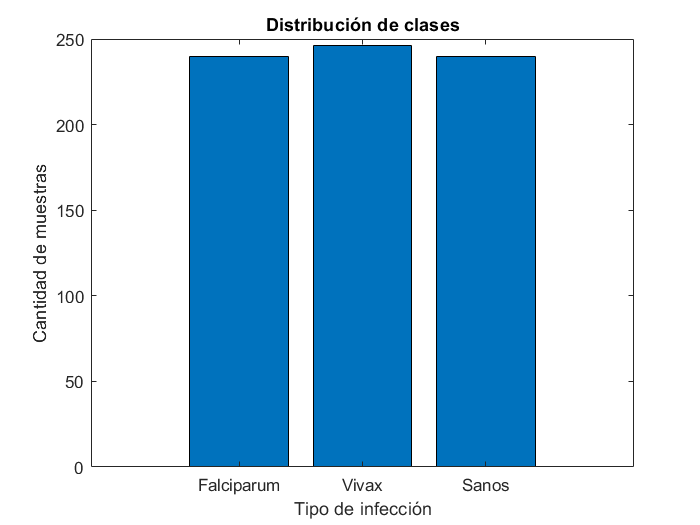

clases = {'Falciparum', 'Vivax', 'Sanos'};
cantidades = [length(idx_falciparum), length(idx_vivax), length(idx_sanos)];

figure;
bar(cantidades)
set(gca, 'XTickLabel', clases);
xlabel('Tipo de infección');
ylabel('Cantidad de muestras');
title('Distribución de clases');

#### **1.4. Estadísticas descriptivas **

Primero de todo, vamos a analizar si la variable es numérica o categórica. En el caso de ser categórica, se indicará mediante un mensaje. En cambio, en el caso de ser numérica, se calculará la media, la moda, el máximo, el mínimo, la derivación estándar, la varianza y el número de datos faltantes por variable.

for i=1:ancho
    x=data.(variables{i});
    if isnumeric(x)
        fprintf ('Variable: %s\n', variables {i});
        fprintf ('Mean %.2f\n', mean (x, 'omitnan'));
        fprintf ('Mode %.2f\n', mode (x));
        fprintf ('Max %.2f\n', max (x));
        fprintf ('Min %.2f\n', min (x));
        fprintf ('Derivación estándar %.2f\n', std (x, 'omitnan'));
        fprintf ('Varianza %.2f\n', (std (x, 'omitnan'))^2);
        missingCount = sum(ismissing(x));
        fprintf('Datos faltantes: %d\n\n', missingCount);
    else
        fprintf ('Variable: %s es categórica.\n', variables{i});
    end
end 

Variable: ImageName es categórica.


Variable: GlobulosBlancosDetectados


Mean 20.88


Mode 19.00


Max 61.00


Min 3.00


Derivación estándar 9.18


Varianza 84.36


Datos faltantes: 0



Variable: ParasitosDetectados


Mean 32.73


Mode 2.00


Max 214.00


Min 0.00


Derivación estándar 35.33


Varianza 1247.86


Datos faltantes: 0



Variable: Leu_median_Area


Mean 3110.84


Mode 3380.00


Max 5970.00


Min 342.50


Derivación estándar 1148.45


Varianza 1318946.59


Datos faltantes: 0



Variable: Leu_median_BoundingBox


Mean 280.15


Mode 182.75


Max 677.25


Min 98.75


Derivación estándar 101.03


Varianza 10206.52


Datos faltantes: 0



Variable: Leu_median_Eccentricity


Mean 0.66


Mode 0.38


Max 0.87


Min 0.38


Derivación estándar 0.10


Varianza 0.01


Datos faltantes: 0



Variable: Leu_median_Circularity


Mean 0.67


Mode 0.31


Max 0.99


Min 0.31


Derivación estándar 0.13


Varianza 0.02


Datos faltantes: 0



Variable: Leu_median_Diameter


Mean 61.45


Mode 56.88


Max 87.19


Min 20.88


Derivación estándar 13.45


Varianza 180.86


Datos faltantes: 0



Variable: Leu_median_Solidity


Mean 0.88


Mode 0.69


Max 0.98


Min 0.69


Derivación estándar 0.05


Varianza 0.00


Datos faltantes: 0



Variable: Leu_median_Perimeter


Mean 235.82


Mode 205.14


Max 364.67


Min 89.07


Derivación estándar 47.57


Varianza 2263.20


Datos faltantes: 0



Variable: Leu_median_Intensity


Mean 0.16


Mode 0.09


Max 0.25


Min 0.09


Derivación estándar 0.04


Varianza 0.00


Datos faltantes: 0



Variable: Par_median_Area


Mean 196.54


Mode 130.00


Max 581.00


Min 83.00


Derivación estándar 68.54


Varianza 4697.80


Datos faltantes: 23



Variable: Par_median_BoundingBox


Mean 313.92


Mode 150.25


Max 1220.75


Min 63.75


Derivación estándar 179.34


Varianza 32164.55


Datos faltantes: 23



Variable: Par_median_Eccentricity


Mean 0.63


Mode 0.32


Max 0.89


Min 0.32


Derivación estándar 0.07


Varianza 0.01


Datos faltantes: 23



Variable: Par_median_Circularity


Mean 0.90


Mode 0.87


Max 1.15


Min 0.69


Derivación estándar 0.06


Varianza 0.00


Datos faltantes: 23



Variable: Par_median_Diameter


Mean 15.57


Mode 14.67


Max 27.20


Min 10.28


Derivación estándar 2.58


Varianza 6.65


Datos faltantes: 23



Variable: Par_median_Solidity


Mean 0.92


Mode 0.91


Max 0.98


Min 0.85


Derivación estándar 0.02


Varianza 0.00


Datos faltantes: 23



Variable: Par_median_Perimeter


Mean 52.17


Mode 42.53


Max 95.57


Min 31.37


Derivación estándar 9.26


Varianza 85.73


Datos faltantes: 23



Variable: Par_median_Intensity


Mean 0.54


Mode 0.24


Max 0.67


Min 0.24


Derivación estándar 0.08


Varianza 0.01


Datos faltantes: 23



#### 1.5. Datos que faltan

Hay que identificar los datos que faltan para decidir qué hacer con ellos y cómo continuar con el EDA.

La única información faltante que tenemos es la relacionada con parásitos, ya que hay imágenes en las que no se detectan parásitos. Sin embargo, al ser muy bajo el porcentaje de datos faltantes (13.5% en todos los casos), se ha decidido ignorar el hecho de que faltan datos.

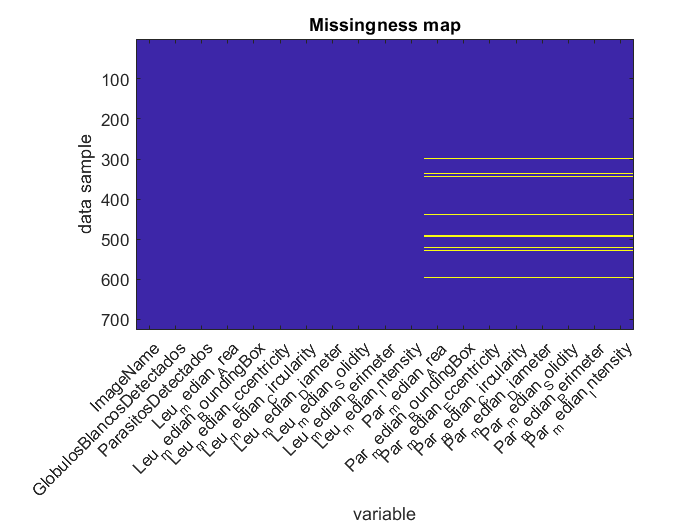

figure;
names = data.Properties.VariableNames;
imagesc(ismissing(data,{'' '.' 'NA' NaN -99}))
xticks(1:length(names));
xticklabels(names);
xtickangle(45)
title('Missingness map');
xlabel('variable');
ylabel('data sample');

summary(data)

Variables:

    ImageName: 726×1 cell array of character vectors

    GlobulosBlancosDetectados: 726×1 double

        Values:

            Min           3   
            Median       19   
            Max          61   

    ParasitosDetectados: 726×1 double

        Values:

            Min           0   
            Median       20   
            Max         214   

    Leu_median_Area: 726×1 double

        Values:

            Min         342.5 
            Median     3335.5 
            Max          5970 

    Leu_median_BoundingBox: 726×1 double

        Values:

            Min         98.75 
            Median     263.25 
            Max        677.25 

    Leu_median_Eccentricity: 726×1 double

        Values:

            Min       0.37724 
            Median    0.67068 
            Max       0.87488 

    Leu_median_Circularity: 726×1 double

        Values


[alto, ancho] = size(data);

Leu_Area_Missing = 99/alto*100

Leu_Area_Missing = 13.6364

Leu_BB_Missing = 99/alto*100

Leu_BB_Missing = 13.6364

Leu_Excentricidad_Missing = 99/alto*100

Leu_Excentricidad_Missing = 13.6364

Leu_Circularidad_Missing = 99/alto*100

Leu_Circularidad_Missing = 13.6364

Leu_Diametro_Missing = 99/alto*100

Leu_Diametro_Missing = 13.6364

Leu_Solidez_Missing = 99/alto*100

Leu_Solidez_Missing = 13.6364

Leu_Perimetro_Missing = 99/alto*100

Leu_Perimetro_Missing = 13.6364

Leu_Intensidad_Missing = 99/alto*100

Leu_Intensidad_Missing = 13.6364


Par_Area_Missing = 98/alto*100

Par_Area_Missing = 13.4986

Par_BB_Missing = 98/alto*100

Par_BB_Missing = 13.4986

Par_Excentricidad_Missing = 98/alto*100

Par_Excentricidad_Missing = 13.4986

Par_Circularidad_Missing = 98/alto*100

Par_Circularidad_Missing = 13.4986

Par_Diametro_Missing = 98/alto*100

Par_Diametro_Missing = 13.4986

Par_Solidez_Missing = 98/alto*100

Par_Solidez_Missing = 13.4986

Par_Perimetro_Missing = 98/alto*100

Par_Perimetro_Missing = 13.4986

Par_Intensidad_Missing = 98/alto*100

Par_Intensidad_Missing = 13.4986


data

data = 726×19 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_BoundingBox    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter    Leu_median_Solidity    Leu_median_Perimeter    Leu_median_Intensity    Par_median_Area    Par_median_BoundingBox    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter    Par_median_Solidity    Par_median_Perimeter    Par_median_Intensity
    _______________________    _________________________    ___________________    _______________    _______________

#### 1.6. Datos duplicados

Además de analizar los datos faltantes, también hay que saber qué datos se repiten para poder continuar con el análisis de forma correcta. Al haber 726 datos diferentes, y sabiendo que la totalidad de los datos es 726, observamos que no hay datos repetidos.

height(unique(data,'rows'))

ans = 726

#### 1.7. Figuras

A continuación se desarrollarán diversos gráficos para analizar las diferencias en la cantidad de glóbulos blancos detectados en las muestras afectadas por la malaria y las no afectadas.

A partir de la bibliografía analizada, se sabe que la cantidad de glóbulos blancos en pacientes sanos es mayor que en pacientes infectados. A su vez, se conoce que la cantidad en pacientes con malaria de tipo *falciparum* es mayor que en los pacientes con el tipo *vivax*.

Viendo el gráfico, se puede decir que la detección es acorde con la bibliografía.

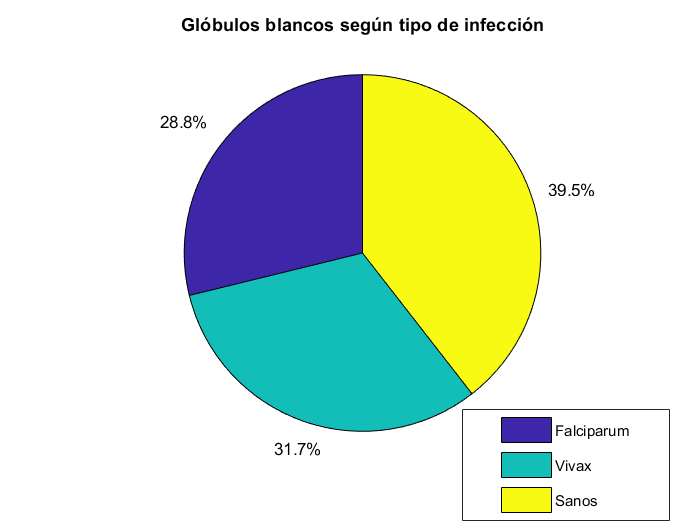

falciparum_globulos = data.GlobulosBlancosDetectados(idx_falciparum);
vivax_globulos = data.GlobulosBlancosDetectados(idx_vivax);
sanos_globulos = data.GlobulosBlancosDetectados(idx_sanos);

falciparum_globulos_cantidad = mean(falciparum_globulos, 'omitnan');
vivax_globulos_cantidad = mean(vivax_globulos, 'omitnan');
sanos_globulos_cantidad = mean(sanos_globulos, 'omitnan');

figure;
valores = [falciparum_globulos_cantidad, vivax_globulos_cantidad, sanos_globulos_cantidad];
porcentajes = 100 * valores / sum(valores);
etiquetas = strcat(string(round(porcentajes,1)), '%'); 
pie(valores, etiquetas);
title('Glóbulos blancos según tipo de infección');
legend({'Falciparum', 'Vivax', 'Sanos'},"Position",[0.66051,0.0079702,0.2971,0.21236])

Se realizará el mismo procedimiento con los parásitos detectados.

A partir de la bibliografía analizada, se sabe que la cantidad de parásitos en pacientes sanos es nula y que la cantidad de parásitos en pacientes con *falciparum* es mayor que en los pacientes con *vivax*.

Viendo el gráfico, se puede decir que la detección no es acorde a la bibliografía ya que nuestro método de segmentación sí que detecta parásitos en los pacientes sanos.

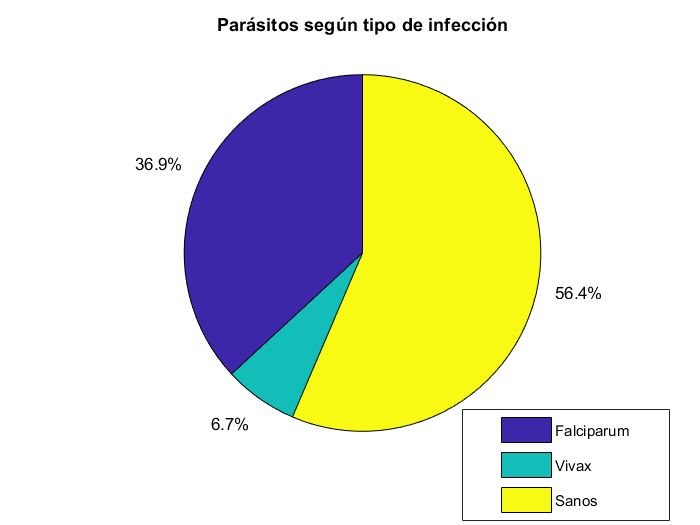

falciparum_parasitos = data.ParasitosDetectados(idx_falciparum);
vivax_parasitos = data.ParasitosDetectados(idx_vivax);
sanos_parasitos = data.ParasitosDetectados(idx_sanos);

falciparum_parasitos_cantidad = median(falciparum_parasitos, 'omitnan');
vivax_parasitos_cantidad = median(vivax_parasitos, 'omitnan');
sanos_parasitos_cantidad = median(sanos_parasitos, 'omitnan');

figure;
valores = [falciparum_parasitos_cantidad, vivax_parasitos_cantidad, sanos_parasitos_cantidad];
porcentajes = 100 * valores / sum(valores);
etiquetas = strcat(string(round(porcentajes,1)), '%'); 
pie(valores, etiquetas);
title('Parásitos según tipo de infección');
legend({'Falciparum', 'Vivax', 'Sanos'},"Position",[0.66051,0.0079702,0.2971,0.21236])

Ahora analizaremos de qué manera las características obtenidas cambian en función del tipo de infección para ver si existe algún patrón.

1.7.1. ÁREA:

Se puede observar que existem muchos valores atípicos respecto al área de los glóbulos blancos (sobre todo en los pacientes con *falciparum* y sanos). En cuanto al área de los parásitos, se pueden observar también muchos valores atípicos en los pacientes con *vivax* y sanos.

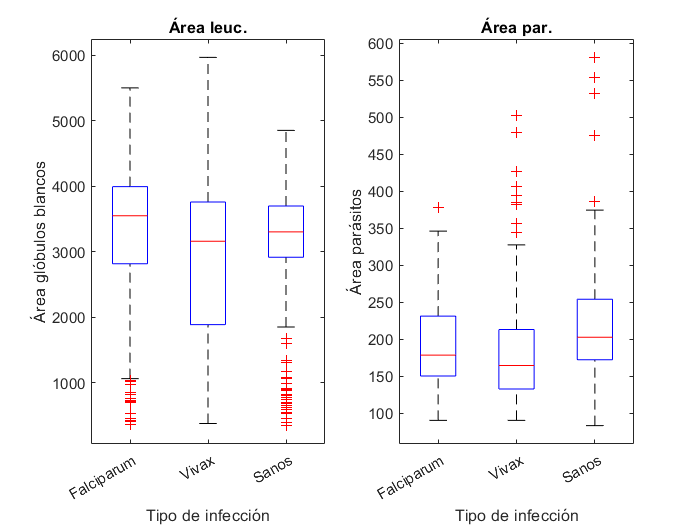

falciparum_globulos_area = data.Leu_median_Area(idx_falciparum);
vivax_globulos_area = data.Leu_median_Area(idx_vivax);
sanos_globulos_area = data.Leu_median_Area(idx_sanos);

valores_area = [falciparum_globulos_area; vivax_globulos_area; sanos_globulos_area];

grupo = [repmat({'Falciparum'}, length(falciparum_globulos_area), 1); 
         repmat({'Vivax'}, length(vivax_globulos_area), 1); 
         repmat({'Sanos'}, length(sanos_globulos_area), 1)];

figure;
subplot(1,2,1);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Área glóbulos blancos');
title('Área leuc.');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
falciparum_parasitos_area = data.Par_median_Area(idx_falciparum);
vivax_parasitos_area = data.Par_median_Area(idx_vivax);
sanos_parasitos_area = data.Par_median_Area(idx_sanos);

valores_area = [falciparum_parasitos_area; vivax_parasitos_area; sanos_parasitos_area];

grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_area), 1); 
         repmat({'Vivax'}, length(vivax_parasitos_area), 1); 
         repmat({'Sanos'}, length(sanos_parasitos_area), 1)];

subplot(1,2,2);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Área parásitos');
title('Área par.');

1.7.2. EXCENTRICIDAD:

Se aprecia que la eccentricidad de los glóbulos blancos en pacientes con *vivax* es algo más alta que en el resto de los casos. Sin embargo, queda clara la similitud entre los valores de eccentricidad de los parásitos entre los tres tipos de casos.

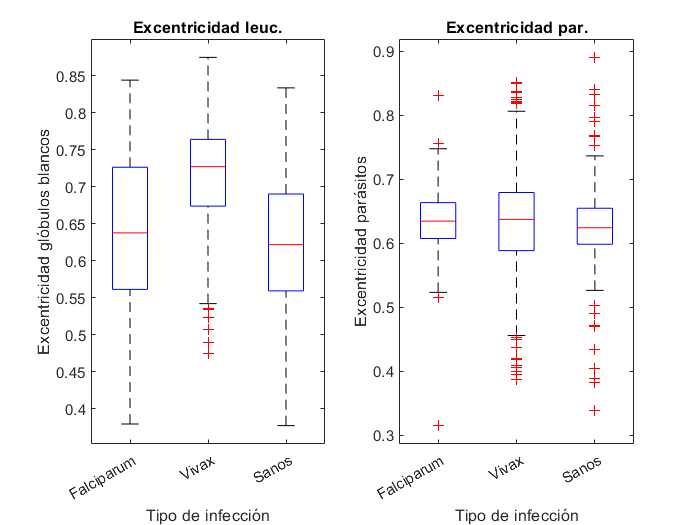

falciparum_globulos_excentricidad = data.Leu_median_Eccentricity(idx_falciparum);
vivax_globulos_excentricidad = data.Leu_median_Eccentricity(idx_vivax);
sanos_globulos_excentricidad = data.Leu_median_Eccentricity(idx_sanos);

valores_area = [falciparum_globulos_excentricidad; vivax_globulos_excentricidad; sanos_globulos_excentricidad];

grupo = [repmat({'Falciparum'}, length(falciparum_globulos_excentricidad), 1); 
         repmat({'Vivax'}, length(vivax_globulos_excentricidad), 1); 
         repmat({'Sanos'}, length(sanos_globulos_excentricidad), 1)];

figure;
subplot(1,2,1);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Excentricidad glóbulos blancos');
title('Excentricidad leuc.');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
falciparum_parasitos_excentricidad = data.Par_median_Eccentricity(idx_falciparum);
vivax_parasitos_excentricidad = data.Par_median_Eccentricity(idx_vivax);
sanos_parasitos_excentricidad = data.Par_median_Eccentricity(idx_sanos);

valores_area = [falciparum_parasitos_excentricidad; vivax_parasitos_excentricidad; sanos_parasitos_excentricidad];

grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_excentricidad), 1); 
         repmat({'Vivax'}, length(vivax_parasitos_excentricidad), 1); 
         repmat({'Sanos'}, length(sanos_parasitos_excentricidad), 1)];

subplot(1,2,2);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Excentricidad parásitos');
title('Excentricidad par.');

1.7.3. CIRCULARIDAD:

La circularidad de los glóbulos blancos no genera ninguna observación de interés. Sin embargo, se pueden apreciar muchos valores atípicos en los tres tipos de infecciones en el caso de la circularidad de los parásitos.

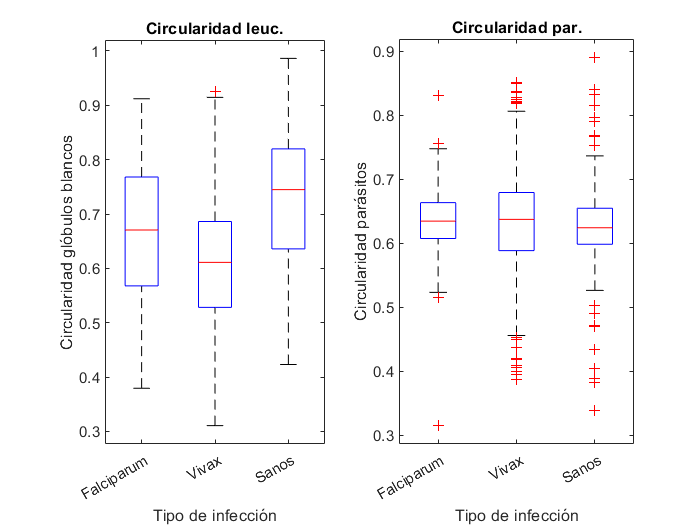

falciparum_globulos_circularidad = data.Leu_median_Circularity(idx_falciparum);
vivax_globulos_circularidad = data.Leu_median_Circularity(idx_vivax);
sanos_globulos_circularidad = data.Leu_median_Circularity(idx_sanos);

valores_area = [falciparum_globulos_circularidad; vivax_globulos_circularidad; sanos_globulos_circularidad];

grupo = [repmat({'Falciparum'}, length(falciparum_globulos_circularidad), 1); 
         repmat({'Vivax'}, length(vivax_globulos_circularidad), 1); 
         repmat({'Sanos'}, length(sanos_globulos_circularidad), 1)];

figure;
subplot(1,2,1);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Circularidad glóbulos blancos');
title('Circularidad leuc.');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
falciparum_parasitos_excentricidad = data.Par_median_Eccentricity(idx_falciparum);
vivax_parasitos_excentricidad = data.Par_median_Eccentricity(idx_vivax);
sanos_parasitos_excentricidad = data.Par_median_Eccentricity(idx_sanos);

valores_area = [falciparum_parasitos_excentricidad; vivax_parasitos_excentricidad; sanos_parasitos_excentricidad];

grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_excentricidad), 1); 
         repmat({'Vivax'}, length(vivax_parasitos_excentricidad), 1); 
         repmat({'Sanos'}, length(sanos_parasitos_excentricidad), 1)];

subplot(1,2,2);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Circularidad parásitos');
title('Circularidad par.');

1.7.4. SOLIDEZ:

La circularidad tanto de los glóbulos blancos como de los parásitos es bastante similar en los tres casos de infección.

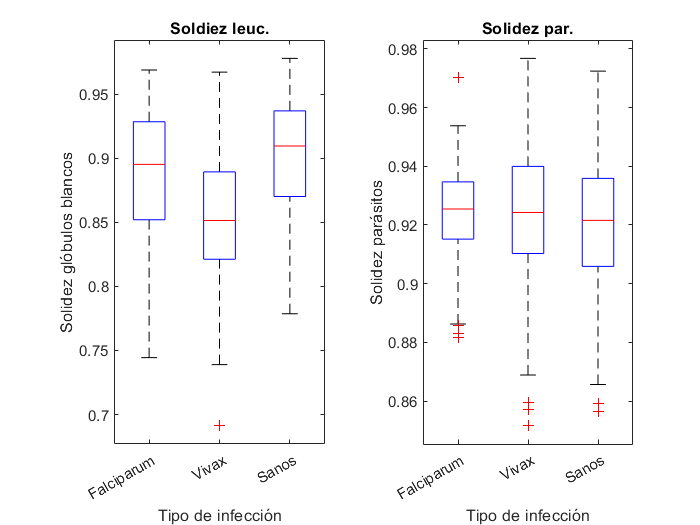

falciparum_globulos_solidez = data.Leu_median_Solidity(idx_falciparum);
vivax_globulos_solidez = data.Leu_median_Solidity(idx_vivax);
sanos_globulos_solidez = data.Leu_median_Solidity(idx_sanos);

valores_area = [falciparum_globulos_solidez; vivax_globulos_solidez; sanos_globulos_solidez];

grupo = [repmat({'Falciparum'}, length(falciparum_globulos_solidez), 1); 
         repmat({'Vivax'}, length(vivax_globulos_solidez), 1); 
         repmat({'Sanos'}, length(sanos_globulos_solidez), 1)];

figure;
subplot(1,2,1);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Solidez glóbulos blancos');
title('Soldiez leuc.');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
falciparum_parasitos_solidez = data.Par_median_Solidity(idx_falciparum);
vivax_parasitos_solidez = data.Par_median_Solidity(idx_vivax);
sanos_parasitos_solidez = data.Par_median_Solidity(idx_sanos);

valores_area = [falciparum_parasitos_solidez; vivax_parasitos_solidez; sanos_parasitos_solidez];

grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_solidez), 1); 
         repmat({'Vivax'}, length(vivax_parasitos_solidez), 1); 
         repmat({'Sanos'}, length(sanos_parasitos_solidez), 1)];

subplot(1,2,2);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Solidez parásitos');
title('Solidez par.');

1.7.5. INTENSIDAD:

Se aprecian muchos valores atípicos en la intensidad de los glóbulos blancos en los pacientes sanos. También se observan valores atípicos en la intensidad de los parásitos en los pacientes sanos, aunque menos que en el caso anterior.

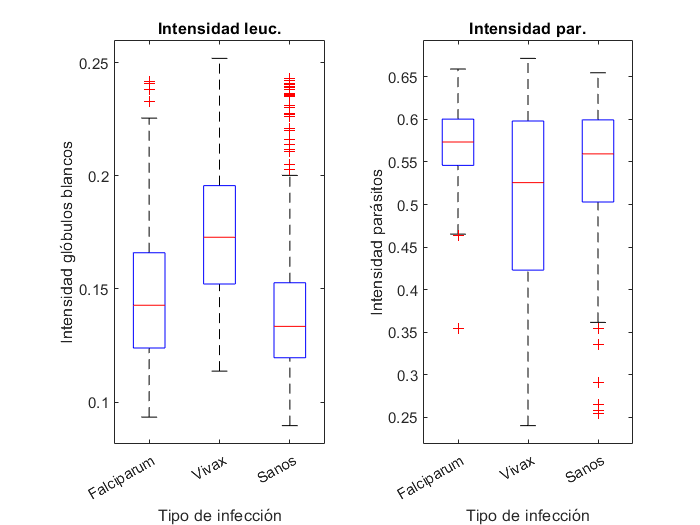

falciparum_globulos_intensidad = data.Leu_median_Intensity(idx_falciparum);
vivax_globulos_intensidad = data.Leu_median_Intensity(idx_vivax);
sanos_globulos_intensidad = data.Leu_median_Intensity(idx_sanos);

valores_area = [falciparum_globulos_intensidad; vivax_globulos_intensidad; sanos_globulos_intensidad];

grupo = [repmat({'Falciparum'}, length(falciparum_globulos_intensidad), 1); 
         repmat({'Vivax'}, length(vivax_globulos_intensidad), 1); 
         repmat({'Sanos'}, length(sanos_globulos_intensidad), 1)];

figure;
subplot(1,2,1);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Intensidad glóbulos blancos');
title('Intensidad leuc.');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
falciparum_parasitos_intensidad = data.Par_median_Intensity(idx_falciparum);
vivax_parasitos_intensidad = data.Par_median_Intensity(idx_vivax);
sanos_parasitos_intensidad = data.Par_median_Intensity(idx_sanos);

valores_area = [falciparum_parasitos_intensidad; vivax_parasitos_intensidad; sanos_parasitos_intensidad];

grupo = [repmat({'Falciparum'}, length(falciparum_parasitos_intensidad), 1); 
         repmat({'Vivax'}, length(vivax_parasitos_intensidad), 1); 
         repmat({'Sanos'}, length(sanos_parasitos_intensidad), 1)];

subplot(1,2,2);
boxplot(valores_area, grupo);
xlabel('Tipo de infección');
ylabel('Intensidad parásitos');
title('Intensidad par.');

data;

#### 1.8. Comprobar valores atípicos

Una vez se pueden ver los valores de forma visual gracias a los *Box Plots*, se va a proceder a desarrollar el *IQR (Interquartile Range) *para ver los valores atípicos de forma matemática.

Se ha decidido ignorar los valores atípicos, ya que no se han encontrado datos suficientes en la bibliografía como para sustituir los *outliers* con dichos valores. Tampoco se ha optado por sustituirlos con la media del resto de valores para no distorsionar los datos.

Group_Names = {'falciparum', 'vivax', 'sanos'};
Group_Indices = {idx_falciparum, idx_vivax, idx_sanos};
Outliers_All = [];

for g = 1:3
    idx = Group_Indices{g};
    data_group = data(idx, :);

    Outliers_count = [];
    Variable_names = {};

    for i = 1:width(data_group)
        var_name = data_group.Properties.VariableNames{i};
        x = data_group.(var_name);

        if isnumeric(x)
            Q1 = quantile(x(~isnan(x)), 0.25);
            Q3 = quantile(x(~isnan(x)), 0.75);
            IQR_val = Q3 - Q1;
    
            lower_limit = Q1 - 1.5 * IQR_val;
            upper_limit = Q3 + 1.5 * IQR_val;
    
            is_outlier = x < lower_limit | x > upper_limit;
            count_outliers = sum(is_outlier, 'omitnan');
    
            Variable_names{end+1} = var_name;
            Outliers_count(end+1) = count_outliers;

            if g == 1
                data.([var_name '_outlier']) = false(height(data), 1); % Crear columna
            end
            data.([var_name '_outlier'])(idx) = is_outlier;
        end
    end
    Outliers_Summary = table(Variable_names', Outliers_count','VariableNames', {'Variable', 'OutliersCount'});
    Outliers_Summary.Group = repmat(Group_Names(g), height(Outliers_Summary), 1);
    Outliers_All = [Outliers_All; Outliers_Summary];
end
display(Outliers_All);

Outliers_All = 54×3 table
              Variable               OutliersCount        Group     
    _____________________________    _____________    ______________

    {'GlobulosBlancosDetectados'}         11          {'falciparum'}
    {'ParasitosDetectados'      }          1          {'falciparum'}
    {'Leu_median_Area'          }         17          {'falciparum'}
    {'Leu_median_BoundingBox'   }          1          {'falciparum'}
    {'Leu_median_Eccentricity'  }          0          {'falciparum'}
    {'Leu_median_Circularity'   }          0          {'falciparum'}
    {'Leu_median_Diameter'      }         24          {'falciparum'}
    {'Leu_median_Solidity'      }          0          {'falciparum'}
    {'Leu_median_Perimeter'     }         14          {'falciparum'}
    {'Leu_median_Intensity'     }          4          {'falciparum'}
    {'Par_median_Area'          }          

data

data = 726×37 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_BoundingBox    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter    Leu_median_Solidity    Leu_median_Perimeter    Leu_median_Intensity    Par_median_Area    Par_median_BoundingBox    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter    Par_median_Solidity    Par_median_Perimeter    Par_median_Intensity    GlobulosBlancosDetectados_outlier    ParasitosDetectados_outlier    Leu_median_Area_outlier    Leu_median_BoundingBox_outlier

#### 1.9. Corrección de alguna variable

A pesar de contar con la variable *BoundingBox*, esta no otorga ninguna información útil para poder desarrollar un análisis. Y es que, esta variable es el resultado de calcular la media de las coordenadas (x e y) y el alto y ancho de los glóbulos blancos y parásitos. De modo que se ha decidido eliminar esta variable.

data.Leu_median_BoundingBox = [];
data.Par_median_BoundingBox = [];
Data_Sin_BoundingBox = data % sin boundingbox

Data_Sin_BoundingBox = 726×35 table
           ImageName           GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Area    Leu_median_Eccentricity    Leu_median_Circularity    Leu_median_Diameter    Leu_median_Solidity    Leu_median_Perimeter    Leu_median_Intensity    Par_median_Area    Par_median_Eccentricity    Par_median_Circularity    Par_median_Diameter    Par_median_Solidity    Par_median_Perimeter    Par_median_Intensity    GlobulosBlancosDetectados_outlier    ParasitosDetectados_outlier    Leu_median_Area_outlier    Leu_median_BoundingBox_outlier    Leu_median_Eccentricity_outlier    Leu

#### 1.10. Correlación

Hay que analizar la correlación entre las variables para ver si las diferentes variables tienen alguna relación entre ellas.

is_numeric = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
numeric_data = data(:, is_numeric);
high_correlations = corr(table2array(numeric_data), 'Rows', 'pairwise');
[row, col] = find(abs(high_correlations) > 0.95 & abs(high_correlations) < 1);
pairs_reported = zeros(0,2);

for k = 1:length(row)
    i = row(k);
    j = col(k);

    if i < j && ~any(ismember([i,j], pairs_reported, 'rows')) 
        var1 = numeric_data.Properties.VariableNames{i};
        var2 = numeric_data.Properties.VariableNames{j};
        fprintf('Variables altamente correlacionadas: %s and %s (r = %.2f)\n', var1, var2, high_correlations(i,j));
    end
end

Variables altamente correlacionadas: Leu_median_Area and Leu_median_Diameter (r = 0.99)
Variables altamente correlacionadas: Par_median_Area and Par_median_Diameter (r = 0.99)
Variables altamente correlacionadas: Par_median_Area and Par_median_Perimeter (r = 0.96)
Variables altamente correlacionadas: Par_median_Diameter and Par_median_Perimeter (r = 0.97)


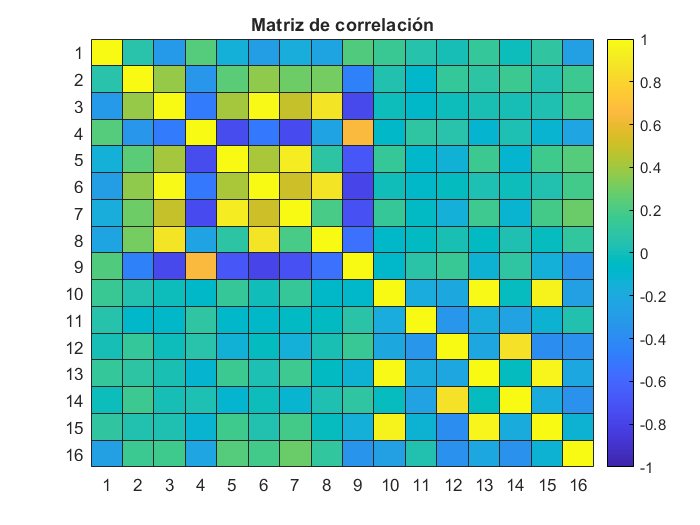


figure;
heatmap(high_correlations, 'Colormap', parula, 'ColorLimits', [-1 1]);
title('Matriz de correlación');

Podemos ver que existen algunas correlaciones, de modo que en el preprocesamiento vamos a eliminar algunas variables.

## 2. PREPROCESAMIENTO

Una vez entendidos nuestros datos, se va a proceder a llevar a cabo el preprocesamiento.

#### 2.1. Eliminar datos redundantes

Tras analizar qué datos están correlacionados (punto 1.10.), se van a eliminar las variables que no nos otorgan valor.

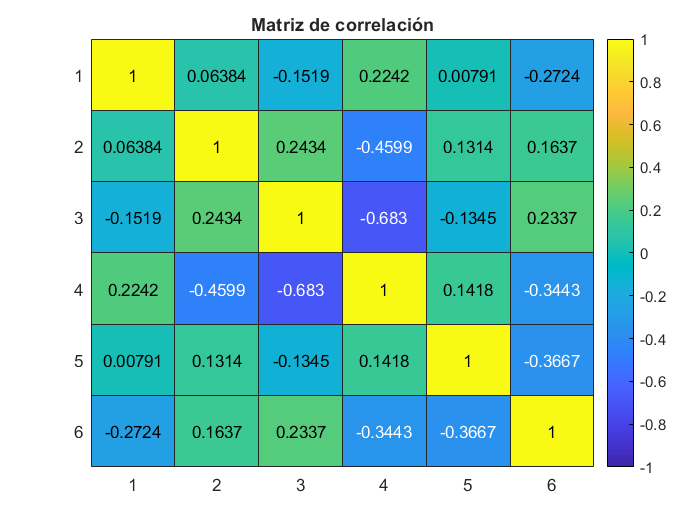

data.ImageName = [];
data.Leu_median_Diameter = [];
data.Par_median_Diameter = [];
data.Leu_median_Eccentricity = [];
data.Par_median_Eccentricity = [];
data.Leu_median_Solidity = [];
data.Par_median_Solidity = [];
data.Leu_median_Area = [];
data.Par_median_Area = [];
data.Leu_median_Perimeter = [];
data.Par_median_Perimeter = [];
Data_Sin_Redundantes = data;

is_numeric = varfun(@isnumeric, data, 'OutputFormat', 'uniform');
numeric_data = data(:, is_numeric);
high_correlations = corr(table2array(numeric_data), 'Rows', 'pairwise');
[row, col] = find(abs(high_correlations) > 0.95 & abs(high_correlations) < 1);
pairs_reported = zeros(0,2);

for k = 1:length(row)
    i = row(k);
    j = col(k);

    if i < j && ~any(ismember([i,j], pairs_reported, 'rows')) 
        var1 = numeric_data.Properties.VariableNames{i};
        var2 = numeric_data.Properties.VariableNames{j};
        fprintf('Variables altamente correlacionadas: %s and %s (r = %.2f)\n', var1, var2, high_correlations(i,j));
    end
end

figure;
heatmap(high_correlations, 'Colormap', parula, 'ColorLimits', [-1 1]);
title('Matriz de correlación');

#### **2.2. Establecer clases**

Antes de continuar con el análisis, vamos a crear una columna que claramente diga qué tipo de infección tiene la muestra.

labels = cell(height(data), 1); 
labels(1:240) = {'falciparum'};
labels(241:486) = {'vivax'};
labels(487:726) = {'sano'};
data = addvars(data, labels, 'Before', 1, 'NewVariableNames', 'Clase');
data

data = 726×25 table
        Clase         GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Circularity    Leu_median_Intensity    Par_median_Circularity    Par_median_Intensity    GlobulosBlancosDetectados_outlier    ParasitosDetectados_outlier    Leu_median_Area_outlier    Leu_median_BoundingBox_outlier    Leu_median_Eccentricity_outlier    Leu_median_Circularity_outlier    Leu_median_Diameter_outlier    Leu_median_Solidity_outlier    Leu_median_Perimeter_outlier    Leu_median_Intensity_outlier    Par_median_Area_outlier    Par_median_BoundingBox_outlier    Par_median_Eccentricity_outlier    Par_median_Circularity_outlier

#### 2.3. Ultimar los datos

Por último, antes de empezar a realizar los modelos, se van a eliminar las columnas que indicaban la presencia de outliers.

columnas_outliers = data.Properties.VariableNames(endsWith(data.Properties.VariableNames, '_outlier'));
data(:, columnas_outliers) = []; 
Data_Preparada = data

Data_Preparada = 726×7 table
        Clase         GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Circularity    Leu_median_Intensity    Par_median_Circularity    Par_median_Intensity
    ______________    _________________________    ___________________    ______________________    ____________________    ______________________    ____________________

    {'falciparum'}               24                        32                    0.75296                     0.125                 0.83439                  0.60092       
    {'falciparum'}               18                        36                    0.69129                   0.12636                 0.88987                   0.5887       
    {'falciparum'}               23             

## 3. MODELO

Primero de todo, se van a mezclar las variables para que al separar el dataset para entrenar y testear el modelo no se cojan solo imágenes de un solo tipo de infección. También se va a preparar el dataset para que una parte se utilice para el entrenamiento de los modelos y la otra para su testeo.

% Mezclar filas
data = data(randperm(height(data)),:)

data = 726×7 table
        Clase         GlobulosBlancosDetectados    ParasitosDetectados    Leu_median_Circularity    Leu_median_Intensity    Par_median_Circularity    Par_median_Intensity
    ______________    _________________________    ___________________    ______________________    ____________________    ______________________    ____________________

    {'vivax'     }               20                         31                   0.57039                  0.12543                  0.86725                  0.59362       
    {'sano'      }               23                        116                   0.68069                  0.13324                  0.91716                  0.56245       
    {'sano'      }               37                       


% Train % Test
cv_out = cvpartition(data.Clase, 'HoldOut', 0.3, 'Stratify', true);
data_train = data(cv_out.training, :);
data_test  = data(cv_out.test, :);

#### 3.1. Logistic Regression: ENFERMO O SANO

Este modelo diagnostica si el paciente está sano o enfermo.

rng(55);

y_train_bin = repmat("enfermo", height(data_train), 1);
y_train_bin(strcmp(data_train.Clase, 'sano')) = "sano";
y_train_bin = categorical(y_train_bin);
tabulate(y_train_bin)

    Value    Count   Percent
  enfermo      341     66.99%
     sano      168     33.01%



features_training = data_train(:, {'Leu_median_Intensity','GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'});
x_train = table2array(features_training);

model_LogisticRegression = fitctree(x_train, y_train_bin);

save('model_LogisticRegression.mat', 'model_LogisticRegression', 'features_training');

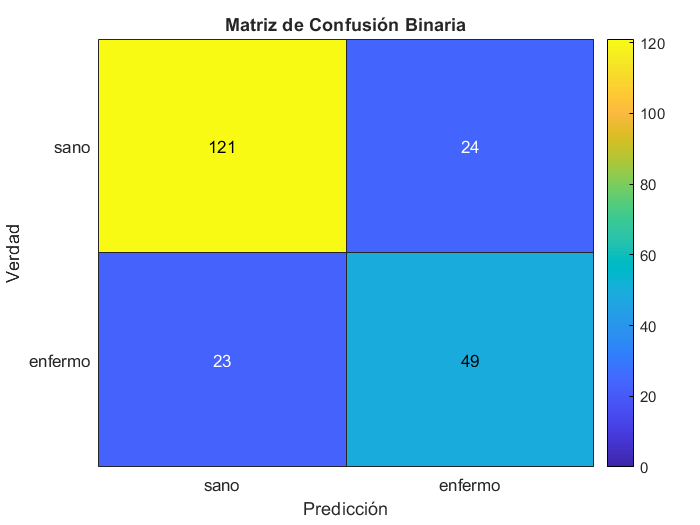

% =============== EVALUAR EL MODELO BINARIO ================= %

% Preparar datos de test
y_test = repmat("enfermo", height(data_test), 1);
y_test(strcmp(data_test.Clase, 'sano')) = "sano";
y_test = categorical(y_test);

features_test = data_test(:, {'Leu_median_Intensity','GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'});
x_test = table2array(features_test);

% Cargar modelo complejo
modelo_PBL = load('model_LogisticRegression.mat');
modelo_PBL = modelo_PBL.model_LogisticRegression;
[predictions, scores] = predict(modelo_PBL, x_test); % Predecir si es falciparum, vivax o sano
y_prediction = categorical(predictions);

% Evaluar el rendimienot del modelo
conf_mat = confusionmat(y_test, y_prediction);
figure;
h = heatmap(["sano","enfermo"], ["sano","enfermo"], conf_mat, ...
    'Colormap', parula, 'ColorLimits', [0 max(conf_mat(:))]);
h.XLabel = 'Predicción';
h.YLabel = 'Verdad';
title('Matriz de Confusión Binaria');


% Accuracy, sensibilidad y especificidad del modelo
clases = categories(y_test);
accuracy = zeros(length(clases),1);
sensibilidad = zeros(length(clases),1);
especificidad = zeros(length(clases),1);
for i = 1:length(clases)
    clase_i = clases{i};
    
    % Verdaderos positivos 
    TP = sum((y_test == clase_i) & (y_prediction == clase_i));
    
    % Falsos negativos 
    FN = sum((y_test == clase_i) & (y_prediction ~= clase_i));
    
    % Verdaderos negativos 
    TN = sum((y_test ~= clase_i) & (y_prediction ~= clase_i));
    
    % Falsos positivos 
    FP = sum((y_test ~= clase_i) & (y_prediction == clase_i));
    
    accuracy(i) = (TP + TN) / (TP + TN + FP + FN);
    sensibilidad(i) = TP / (TP + FN);
    especificidad(i) = TN / (TN + FP);
    
    fprintf('Clase: %s\n', clase_i);
    fprintf('Accuracy: %.2f%%\n', accuracy(i)*100);
    fprintf('Sensibilidad: %.2f%%\n', sensibilidad(i)*100);
    fprintf('Especificidad: %.2f%%\n', especificidad(i)*100);
end

Clase: enfermo


Accuracy: 78.34%


Sensibilidad: 83.45%


Especificidad: 68.06%


Clase: sano


Accuracy: 78.34%


Sensibilidad: 68.06%


Especificidad: 83.45%




% =============== VALIDACIÓN - PREDECIR UNA NUEVA IMAGEN ================= %

% nueva_imagen_data = readtable('Prueba_S.csv');
% x_nueva = table2array(nueva_imagen_data(:, {'Leu_median_Intensity','GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'}));
% 
% [predictions, scores] = predict(modelo_PBL, x_nueva);
% 
% for i = 1:height(nueva_imagen_data)
%      clase_predicha = string(predictions(i));
%      probabilidades = scores(i,:);
% 
%      fprintf('\n--- Imagen %d ---\n', i);
%      fprintf('Predicción: %s\n', string(clase_predicha));
%      disp('Probabilidades por clase:');
%      disp(table(modelo_PBL.ClassNames, probabilidades', 'VariableNames', {'Clase', 'Probabilidad'}));
% end

#### 3.2. Random Forest (100): SOLO SI ESTÁ ENFERMO

En el caso de los pacientes enfermos, el algoritmo también dirá qué tipo de malaria (*falciparum* o *vivax*) tiene.

rng(55);

data_enfermo = data_train(~strcmp(data_train.Clase, 'sano'), :); % solo enfermos
Y_train = categorical(data_enfermo.Clase);
features_training = data_enfermo(:, {'GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'});
X_train = table2array(features_training);

cv_enfermos = cvpartition(height(data_enfermo), 'KFold', 5);

template = templateTree('MinLeafSize', 10);
model_RandomForest100 = fitcensemble(X_train, Y_train, ...
    'Method', 'Bag', ...
    'Learners', template, ...
    'NumLearningCycles', 100, ...
    'CVPartition', cv_enfermos);
save('model_RandomForest100.mat', 'model_RandomForest100');

% =============== EVALUAR EL MODELO ================= %
modelo_PBL = load('model_RandomForest100.mat');
modelo_PBL = modelo_PBL.model_RandomForest100;

loss_modelo = kfoldLoss(modelo_PBL)

loss_modelo = 0.2434

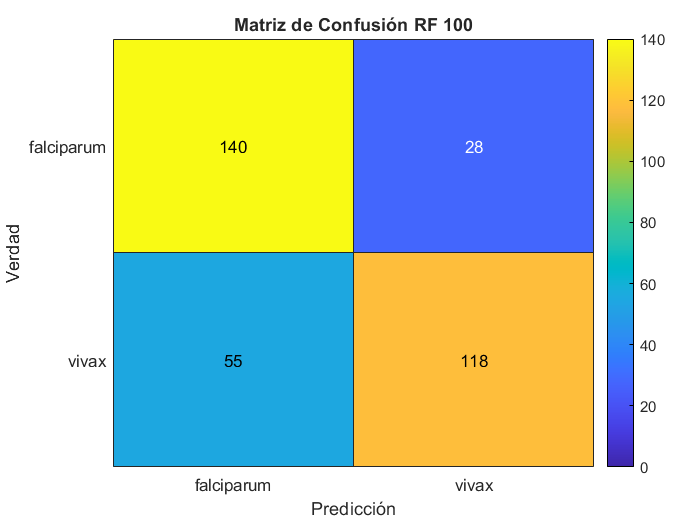

Y_pred = kfoldPredict(modelo_PBL);
Y_train = categorical(Y_train);  
Y_pred = categorical(Y_pred);

% Confusion matrix
conf_mat = confusionmat(Y_train, Y_pred);
figure;
h = heatmap(["falciparum","vivax"], ["falciparum","vivax"], conf_mat, ...
    'Colormap', parula, 'ColorLimits', [0 max(conf_mat(:))]);h.XLabel = 'Predicción';
h.YLabel = 'Verdad';
title('Matriz de Confusión RF 100');


% Accuracy, Sensibilidad y Especifidad
clases = categories(Y_train);
accuracy = zeros(length(clases),1);
sensibilidad = zeros(length(clases),1);
especificidad = zeros(length(clases),1);
for i = 1:length(clases)
    clase_i = clases{i};
    
    % Verdaderos positivos 
    TP = sum((Y_train == clase_i) & (Y_pred == clase_i));
    
    % Falsos negativos 
    FN = sum((Y_train == clase_i) & (Y_pred ~= clase_i));
    
    % Verdaderos negativos 
    TN = sum((Y_train ~= clase_i) & (Y_pred ~= clase_i));
    
    % Falsos positivos 
    FP = sum((Y_train ~= clase_i) & (Y_pred == clase_i));
    
    accuracy(i) = (TP + TN) / (TP + TN + FP + FN);
    sensibilidad(i) = TP / (TP + FN);
    especificidad(i) = TN / (TN + FP);
    
    fprintf('Clase: %s\n', clase_i);
    fprintf('Accuracy: %.2f%%\n', accuracy(i)*100);
    fprintf('Sensibilidad: %.2f%%\n', sensibilidad(i)*100);
    fprintf('Especificidad: %.2f%%\n', especificidad(i)*100);
end

Clase: falciparum


Accuracy: 75.66%


Sensibilidad: 83.33%


Especificidad: 68.21%


Clase: vivax


Accuracy: 75.66%


Sensibilidad: 68.21%


Especificidad: 83.33%



% =============== VALIDACIÓN - PREDECIR UNA NUEVA IMAGEN ================= %

% nueva_imagen_data = readtable('Prueba_F1.csv');
% 
% x_nueva = table2array(nueva_imagen_data(:, {'GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'}));
% 
% [predictions, scores] = predict(modelo_PBL.Trained{1}, x_nueva); % Predecir si es falciparum, vivax o sano
% 
% for i = 1:height(nueva_imagen_data)
%     clase_predicha = string(predictions(i));
%     probabilidades = scores(i,:);  
% 
%     % Densidad parasitaria (parásitos/μL)
%     parasitos = nueva_imagen_data.ParasitosDetectados(i);
%     leucocitos = nueva_imagen_data.GlobulosBlancosDetectados(i);
% 
%     if (leucocitos + parasitos == 0)
%         densidad_parasitaria = 0;
%     else
%         factor = 400; % es el mas comun --> convierte la proporcion de parasitos en una densidad parasitaria
%         densidad_parasitaria = (parasitos / (leucocitos + parasitos)*factor);
%     end
% 
%     % Clasificar segun los umbrales
%     if strcmp(clase_predicha, 'sano')
%         categoria_densidad = 'Sano';
%     else
%         if strcmp(clase_predicha, 'falciparum')
%             if densidad_parasitaria < 800
%                 categoria_densidad = 'Baja';
%             elseif densidad_parasitaria <= 4000
%                 categoria_densidad = 'Moderada';
%             else
%                 categoria_densidad = 'Alta';
%             end
%         end
%         if strcmp(clase_predicha, 'vivax')
%             if densidad_parasitaria < 800
%                 categoria_densidad = 'Baja';
%             elseif densidad_parasitaria <= 2400
%                 categoria_densidad = 'Moderada';
%             else
%                 categoria_densidad = 'Alta';
%             end
%         end
%     end
% 
%     fprintf('\n--- Imagen %d ---\n', i);
%     fprintf('Predicción: %s\n', string(clase_predicha));
%     disp('Probabilidades por clase:');
%     disp(table(modelo_PBL.ClassNames, probabilidades', 'VariableNames', {'Clase', 'Probabilidad'}));
%     fprintf('Densidad parasitaria estimada: %.2f parásitos/μL\n', densidad_parasitaria);
%     fprintf('Densidad parasitaria: %s\n', categoria_densidad);
% end

#### 3.3. Validación completa

Nuestros dos modelos funcionan conjuntamente, de modo que se han concatenado para que funcionen seguidos: primero se diagnostica si el paciente está sano o enfermo y luego, en los casos en los que está enfermo, se diagnostica el tipo de malaria y la densidad parasitaria.

modelo_PBL_bin = load('model_LogisticRegression.mat');
modelo_PBL_bin = modelo_PBL_bin.model_LogisticRegression;

modelo_PBL = load('model_RandomForest100.mat');
modelo_PBL = modelo_PBL.model_RandomForest100;

nueva_imagen_data = readtable('Prueba_F2.csv');

% ENFERMO VS SANO
x_nueva_bin = table2array(nueva_imagen_data(:, {'Leu_median_Intensity','GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'}));
[predictions_bin, scores_bin] = predict(modelo_PBL_bin, x_nueva_bin);

% FALCIPARUM VS VIVAX
x_nueva = table2array(nueva_imagen_data(:, {'GlobulosBlancosDetectados','Leu_median_Circularity','Par_median_Intensity'}));
[predictions, scores] = predict(modelo_PBL.Trained{1}, x_nueva); 

for i = 1:height(nueva_imagen_data)
    fprintf('\n--- Imagen %d ---\n', i);
    fprintf('Predicción binaria: %s\n', string(predictions_bin(i)));

    if string(predictions_bin(i)) == "enfermo"
        clase_final = string(predictions(i));

        % Densidad parasitaria
        parasitos = nueva_imagen_data.ParasitosDetectados(i);
        leucocitos = nueva_imagen_data.GlobulosBlancosDetectados(i);

        if (leucocitos + parasitos == 0)
            densidad_parasitaria = 0;
        else
            factor = 400; % es el mas comun --> convierte la proporcion de parasitos en una densidad parasitaria
            densidad_parasitaria = (parasitos / (leucocitos + parasitos)*factor);
        end
        if strcmp(clase_final, 'falciparum')
            if densidad_parasitaria < 800
               categoria_densidad = 'Baja';
            elseif densidad_parasitaria <= 4000
               categoria_densidad = 'Moderada';
            else
               categoria_densidad = 'Alta';
            end
        end
        if strcmp(clase_final, 'vivax')
            if densidad_parasitaria < 800
               categoria_densidad = 'Baja';
            elseif densidad_parasitaria <= 2400
               categoria_densidad = 'Moderada';
            else
               categoria_densidad = 'Alta';
            end
        end
        fprintf('Tipo de malaria: %s\n', clase_final);
        fprintf('Densidad parasitaria: %.2f parásitos/µL\n', densidad_parasitaria);
        fprintf('Categoría de densidad: %s\n', categoria_densidad);
    else
        fprintf('Diagnóstico final: sano\n');
    end
end


--- Imagen 1 ---


Predicción binaria: sano


Diagnóstico final: sano



--- Imagen 2 ---


Predicción binaria: enfermo


Tipo de malaria: falciparum


Densidad parasitaria: 241.86 parásitos/µL


Categoría de densidad: Baja



--- Imagen 3 ---


Predicción binaria: sano


Diagnóstico final: sano



--- Imagen 4 ---


Predicción binaria: enfermo


Tipo de malaria: falciparum


Densidad parasitaria: 250.00 parásitos/µL


Categoría de densidad: Baja



--- Imagen 5 ---


Predicción binaria: sano


Diagnóstico final: sano



--- Imagen 6 ---


Predicción binaria: enfermo


Tipo de malaria: falciparum


Densidad parasitaria: 222.22 parásitos/µL


Categoría de densidad: Baja



--- Imagen 7 ---


Predicción binaria: sano


Diagnóstico final: sano



--- Imagen 8 ---


Predicción binaria: sano


Diagnóstico final: sano



--- Imagen 9 ---


Predicción binaria: sano


Diagnóstico final: sano



--- Imagen 10 ---


Predicción binaria: enfermo


Tipo de malaria: falciparum


Densidad parasitaria: 346.43 parásitos/µL


Categoría de densidad: Baja



--- Imagen 11 ---


Predicción binaria: sano


Diagnóstico final: sano



--- Imagen 12 ---


Predicción binaria: sano


Diagnóstico final: sano



--- Imagen 13 ---


Predicción binaria: enfermo


Tipo de malaria: falciparum


Densidad parasitaria: 173.33 parásitos/µL


Categoría de densidad: Baja



--- Imagen 14 ---


Predicción binaria: enfermo


Tipo de malaria: falciparum


Densidad parasitaria: 240.00 parásitos/µL


Categoría de densidad: Baja



--- Imagen 15 ---


Predicción binaria: enfermo


Tipo de malaria: falciparum


Densidad parasitaria: 138.46 parásitos/µL


Categoría de densidad: Baja



--- Imagen 16 ---


Predicción binaria: sano


Diagnóstico final: sano



--- Imagen 17 ---


Predicción binaria: enfermo


Tipo de malaria: falciparum


Densidad parasitaria: 224.00 parásitos/µL


Categoría de densidad: Baja



--- Imagen 18 ---


Predicción binaria: enfermo


Tipo de malaria: falciparum


Densidad parasitaria: 218.18 parásitos/µL


Categoría de densidad: Baja
